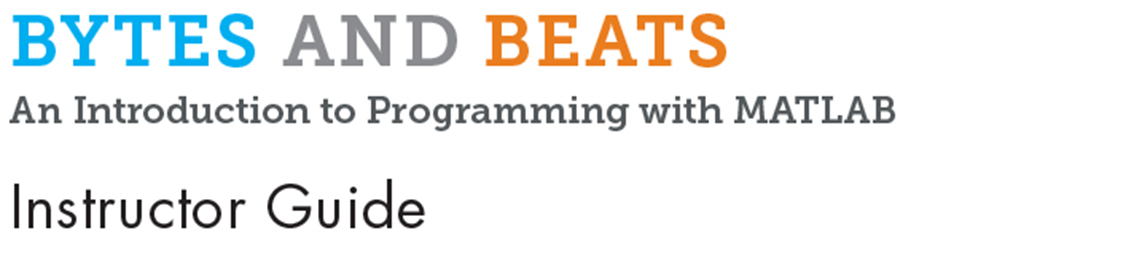

# Module 10: Tunable Parameters and 'If' Statements

**Prerequisite Domain Knowledge:** Functions, Loops 

**Expected Completion Time: **60 minutes

## Adding tunable parameters to script

*Expected Duration: 20 minutes*

### Learning Objectives

- Learn to create tunable parameters in code

- Changing pitch and duration of tunes

- Use scalar multiplication

### Motivation

Now that students understand how to use functions and loops, we can continue to build on this by creating a few parameters. Tweaking these parameters will allow students to create endless variations of the same tune.

### Materials

- MATLAB®

### Solution

 
open TuningParameters_solution.mlx

### Steps

#### PART A – Revisiting loops

- Have the students open the Live Script "TuningParameters.mlx":

 
open TuningParameters.mlx

- This script is just like the one's students created in a previous module for the Happy Birthday song, except that the frequencies are different. Tell the students to run the script. They will hear the same note played 5 times. That is not what we want to hear though. We want to play the frequencies in `freq` for time durations in `t_dur` and pause durations in `p_dur`.

- There are four corrections needed in the 'for' loop to get the right tune. Ask the students if they can spot these. Correct one by one along with the students as they discover the errors. The students should be able to guide the process. Here is the corrected loop:

- You can also replace `14` by `length(freq)`for better reusability of the code.

- You can run the script after each change to help the students identify what needs changing.

- Run the script one final time.

#### PART B – Creating tunable parameters

- In previous modules, students learned how to multiply a scalar with a vector. Revisit the concept. See if the students remember by asking them what the output of the following command will be:

- Ans is [2, 4, 6]

- In the script, we have three numeric vectors`: freq, t_dur, p_dur`

- Ask the students to multiply each vector by 2 and discuss what will happen before they run the script. 

- We multiplied all the frequencies by 2, so the pitch will increase by twice. We also multiplied the durations by 2, so the speed will reduce by two times.

- Run the script.

- Now, replace these scalar multipliers by new variables: `freq_mul`, `t_dur_mul` and `p_dur_mul.` Then assign scalar values to these before multiplying. Here is how the code must look:

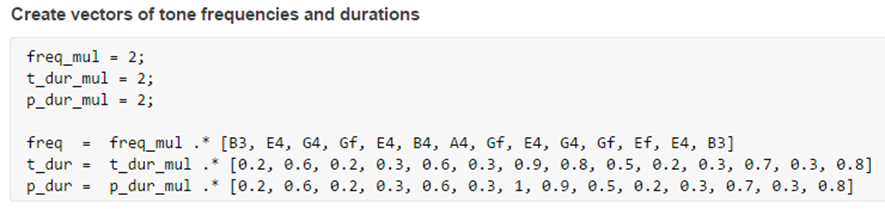                     

- These multiplier variables are now "parameters" of their code whose values they can change for different effects.

- Let the students experiment with other scalars between 0 and 5. They should be able to relate the values of these multipliers to the sound that they hear. 

- For e.g., try: 

In this example, they should hear some overlap in the notes because the pause between notes (1 seconds) is less than how long we want each note to play (1.5 seconds).

***NOTE-*** Multiplying `p_dur` by a large number will make the tune go very slow. 

Multiplying `freq `by a large number will make the pitch too high.

## Script to function

*Expected Duration: 20 minutes*

### Learning Objectives

- Write a function 

- Understand how input and output arguments work

### Motivation

Students have been using functions that were pre-defined for them. They did not have to know how functions like `find`, `join `or `sineSound` work. They could simply use them by knowing what the function does. They were also able to use these functions over and over. Students will learn to write their own function for the same benefits – reusability and abstraction.

### Materials

- MATLAB

### Steps

- Tell the students that they will create their own function in this activity. So far, they have used functions without knowing internal details. Tell the students that this is the benefit of functions. They can be used only by knowing the syntax and what they do.

- Though MATLAB provides thousands of commonly used functions, programmers often write their own functions to do specific tasks that they need to perform repeatedly with different inputs.  In this activity, we will convert the Live script from the previous activity into a Live function.

Tell the students to open the file "tune.mlx":

 
open tune.mlx

- Spend some time discussing what the file contains. 

- It contains three lines of code. 

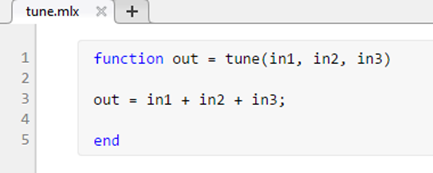

- The words highlighted in blue are called "keywords". We have seen blue highlights before: `for … end`

- In this file, the first keyword` function `tells MATLAB that this is the start of a function. The last keyword,`end `tells us where the function ends.

- Now, discuss the first line: 

 This is the syntax (grammar) for declaring a function. 

- The name of the function is `'tune'` which must be same as the name of the file. 

- `in1,in2`and `in3` are inputs the function accepts.

- `out`is the output given by the function.

- Between the first and the last line is the "body" of the function. This is a set of operations performed on the inputs to give the output. The body can contain any code. It can also call other functions. Ask the students what this function is doing.

- It is adding the three inputs and assigning the answer to the output.

Notice the "Run" button is disabled. This is because, the function cannot run as is. It needs real input values to replace the placeholders in1, in2 and in3

- Show the students by executing this in the **Command Window**:

- This can be a challenging concept. Students must understand that the input and output names are just placeholders for actual input values. They can, in fact, perform the same calculation and save output in a different variable in place of out:

- Similarly, the inputs can have different variables as well:

Let them try some more.

Have the students follow your lead over the rest of this activity.

- We will modify this function to play our theme song from the previous activity. The function will take the value of multipliers (tuning parameters) as inputs.  

- Tell the students to delete this line from the "tune.mlx":

This is how the file should look now:

 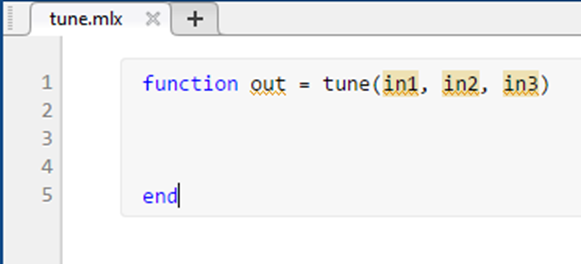

- Next, tell the students to copy the code from their TuningParameters.mlx file and paste it in the body of the` tune `function. This is how the result will look:

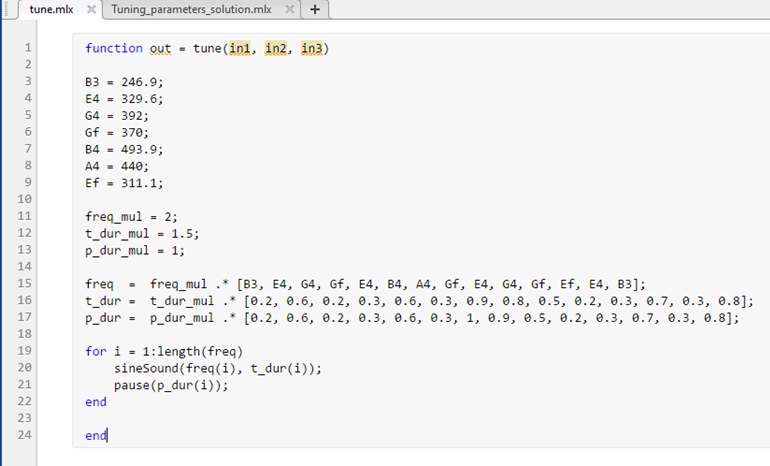

- Now, we want to let the function take the three multipliers (tunable parameters) as inputs. Here is how we will achieve that in two steps:

- Delete the lines defining the values of `freq_mul, t_dur_mul, p_dur_mul `(highlighted above)

- Change the three input names to `freq_mul, t_dur_mul, p_dur_mul`

- Here is what the code should be after that:

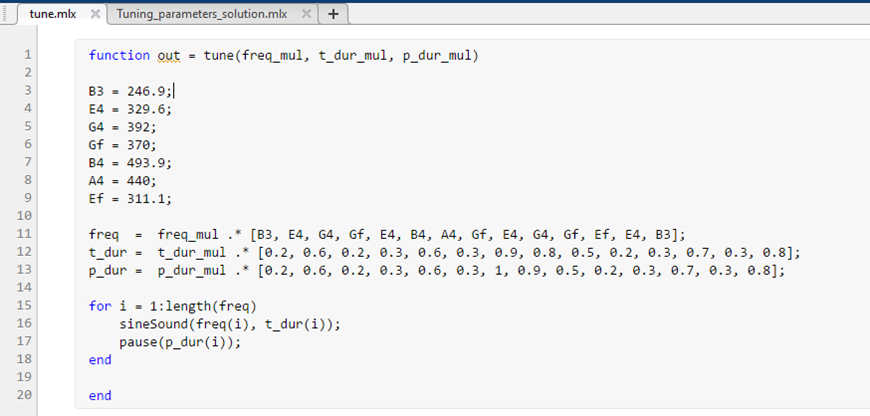

- As the students may notice, the output is underlined orange. If you hover the cursor over it, it warns that the output has not been set. Recall that functions need not return any output. In this case, the function plays a tune. It does not produce any number or string to return. So, we can remove the `out`variable and change the line to:

- Click the "Save" button

- This is it! The students have successfully created a function. They can now use it with different input multipliers. Try:

- They can, in fact, close the file and still use this function. They only need to know that the `tune()` function takes three numeric inputs. The first is a frequency multiplier, second is a time duration multiplier and the third is a pause duration multiplier. It returns no output. 

- Congratulate the students on creating their first function. Recap the important points in a discussion:

- Functions are like scripts in that they contain code to perform a specialized task.

- Unlike a script, functions can take input arguments and return output arguments.

- To use a function, you only must know its name, what inputs it can take and what outputs it will return.

- They make it easy to reuse some code with different inputs.

## Using 'if' statements

*Expected Duration: 20 minutes*

### Learning Objectives

- Conditional branching 

### Motivation

In programming, decision making is required for deciding which statements will execute in what order. To make music, students will need code that makes decisions based on certain conditions. `if… elseif… else `statements are a tool that will be useful over the rest of the course

### Materials

- MATLAB

### Solution

 
open find_grade_solution.mlx

### Steps

The students will write a program to determine a grade based on the score in an exam. Tell the students to open the file “find_grade.mlx”

 
open find_grade.mlx

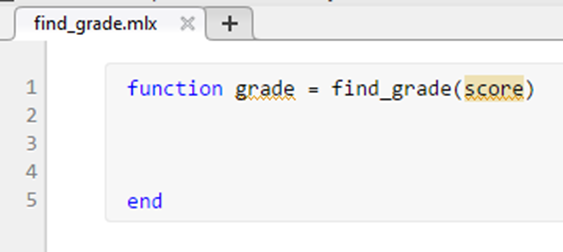

- This function takes in the exam score as in input and returns the corresponding grade as the output.

Now, inside the body of the function, we will write code to determine whether this score corresponds to an A grade or not by using the ‘if’ keyword as shown below. Ask the students to follow along with you:

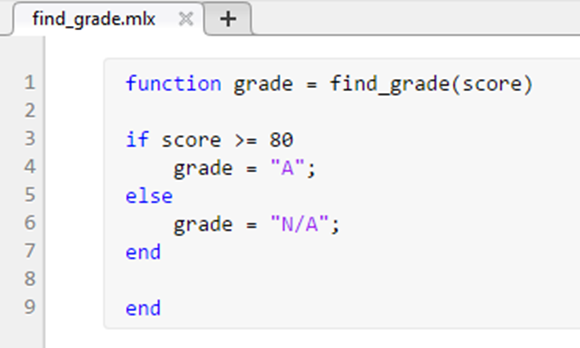

- Like the ‘for’ loop and the ‘function’ keyword, ‘if’ also gets an ‘end’ keyword to mark the beginning and end of the ‘if’ statement. We follow the ‘if’ keyword with a condition that needs checking (`score >= 80`) which can only return a ‘true’ or ‘false’ result. IF the result is true, the code inside the ‘if’ block is executed, otherwise the code inside the ‘else’ block is executed.

Ask the students to call this function from the **Command Window**, first with a score above 80 and ask them what they expect the grade to be. It should be “A”. Then calling the function with a score below 80 should give them a “N/A” grade.

We can also modify the code to check if the student got a B or C grade by including an`elseif `statement. Tell the students that any number of `elseif` statements can be included between the `if` and `else` statements to specify more conditions if the previous conditions are not true:

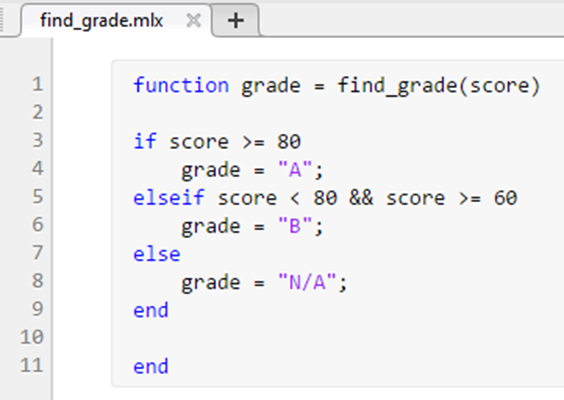

- The "`&&" `operator checks two or more conditions and only returns true if ***both ***are true.

- Ask the students what the following command will now return

- It should now return grade B as the output.

Tell the students to add another `elseif` statement before the else statement to check for C grade (score between 60 and 40).

Optionally, discuss these points at the end or when they are raised as questions:

- When a condition is satisfied, MATLAB will execute the statements for that condition and will not check the remaining conditions following it.

- The >= operator checks if a value is "greater than or equal to".

- Try adding multiple lines of code for one of the conditions.

- Try adding code after `end` statement.

© COPYRIGHT 2024 by The MathWorks®, Inc.